# **Pentagon**

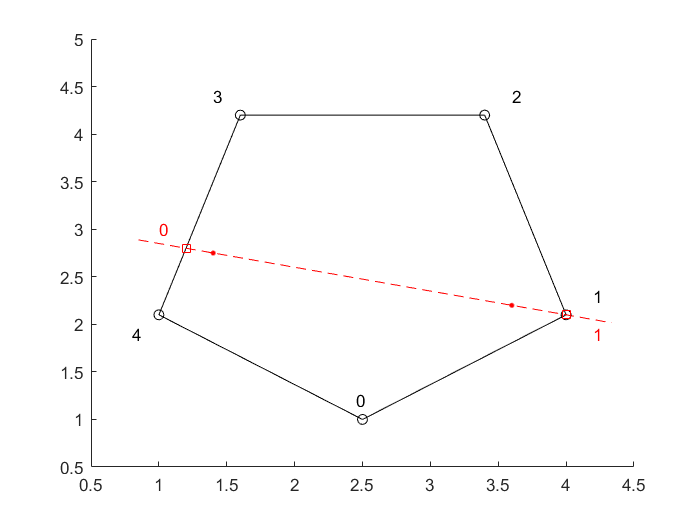

width = 1.0;

color1 = [45, 147, 250] / 255;
color2 = [2, 189, 8] / 255;
color3 = [240, 236, 10] / 255;

points = [
    2.5, 1.0;
    4.0, 2.1;
    3.4, 4.2;
    1.6, 4.2;
    1.0, 2.1];
polygon = polyshape(points);
segment = [1.4, 2.75; 3.6, 2.2];
intersection = [
    1.2, 2.8
    4.0, 2.1];

tangent = segment(2, :) - segment(1, :);
start = segment(1, :) - 1*tangent/4;
fine  = segment(2, :) + tangent/3;

figure;
hold on;

plot(polygon, "FaceColor", "w");
plot([start(1), fine(1)], [start(2), fine(2)], 'r--');
plot(points(:, 1),points(:, 2), 'ko');
plot(intersection(:, 1), intersection(:, 2), 'rs');
plot(segment(:, 1), segment(:, 2), 'r.', "MarkerSize", 9);

text(points(1, 1) - 0.05, points(1, 2) + 0.2, "0");
text(points(2, 1) + 0.2, points(2, 2) + 0.2, "1");
text(points(3, 1) + 0.2, points(3, 2) + 0.2, "2");
text(points(4, 1) - 0.2, points(4, 2) + 0.2, "3");
text(points(5, 1) - 0.2, points(5, 2) - 0.2, "4");

text(intersection(1, 1) - 0.2, intersection(1, 2) + 0.2, "0", "Color", "r");
text(intersection(2, 1) + 0.2, intersection(2, 2) - 0.2, "1", "Color", "r");

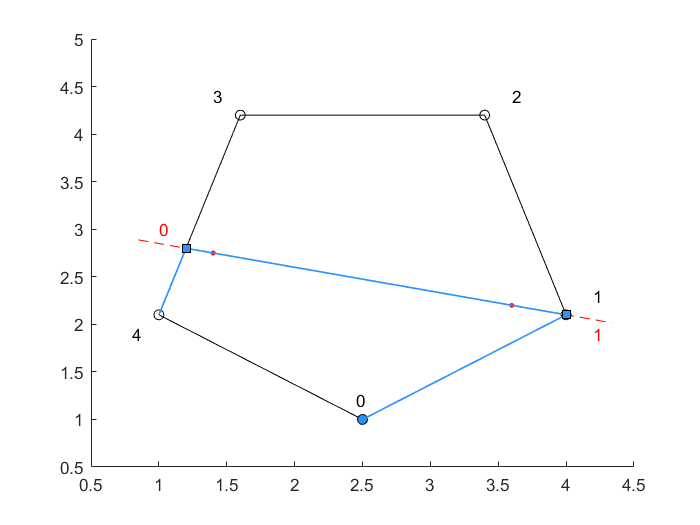


plot(points(1, 1), points(1, 2), "ko", "MarkerFaceColor", color1)
plot([points(1, 1), intersection(2, 1)], [points(1, 2), intersection(2, 2)], "Color", color1, "LineWidth", width);
plot([intersection(1, 1), intersection(2, 1)], [intersection(1, 2), intersection(2, 2)], "Color", color1, "LineWidth", width);
plot([points(5, 1), intersection(1, 1)], [points(5, 2), intersection(1, 2)], "Color", color1, "LineWidth", width);
plot(intersection(1, 1), intersection(1, 2), "ks", "MarkerFaceColor", color1);
plot(intersection(2, 1), intersection(2, 2), "ks", "MarkerFaceColor", color1);

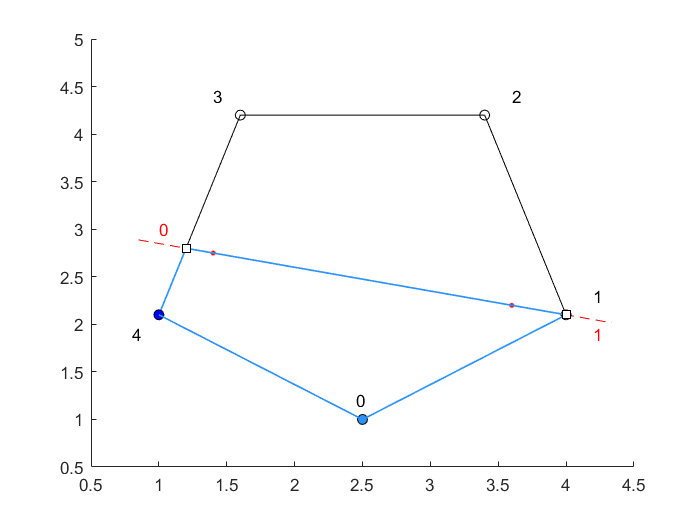

plot(intersection(1, 1), intersection(1, 2), "ks", "MarkerFaceColor", "auto");
plot(intersection(2, 1), intersection(2, 2), "ks", "MarkerFaceColor", "auto");

plot(points(5, 1), points(5, 2), "ko", "MarkerFaceColor", color1);
plot([points(5, 1), points(1, 1)], [points(5, 2), points(1, 2)], "Color", color1, "LineWidth", width);

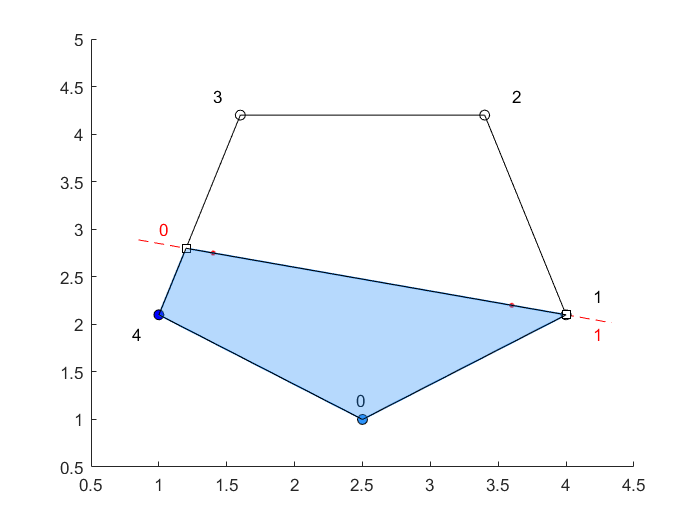

points1 = [
    2.5, 1.0
    4.0, 2.1
    1.2, 2.8
    1.0, 2.1];
polygon1 = polyshape(points1);
plot(polygon1, "FaceColor", color1);

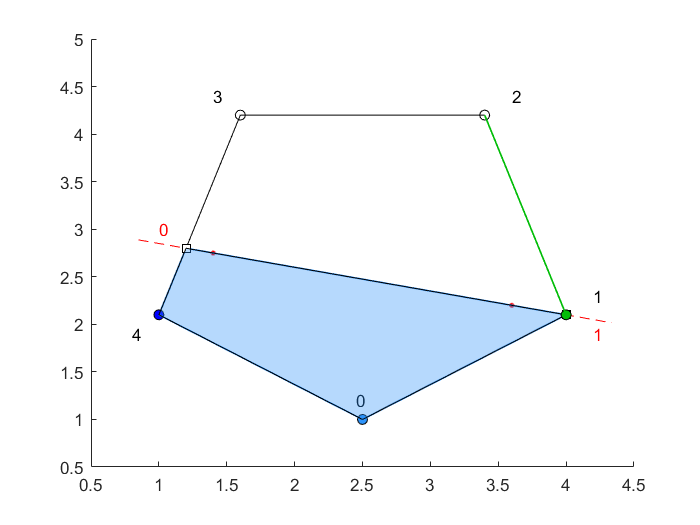

plot(points(2, 1), points(2, 2), "ko", "MarkerFaceColor", color2)
plot([points(3, 1), points(2, 1)], [points(3, 2), points(2, 2)], "Color", color2, "LineWidth", width);

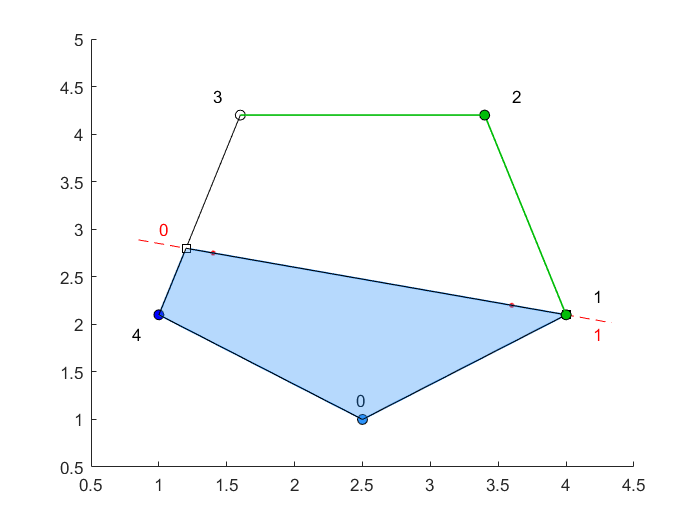


plot(points(3, 1), points(3, 2), "ko", "MarkerFaceColor", color2)
plot([points(3, 1), points(4, 1)], [points(3, 2), points(4, 2)], "Color", color2, "LineWidth", width);

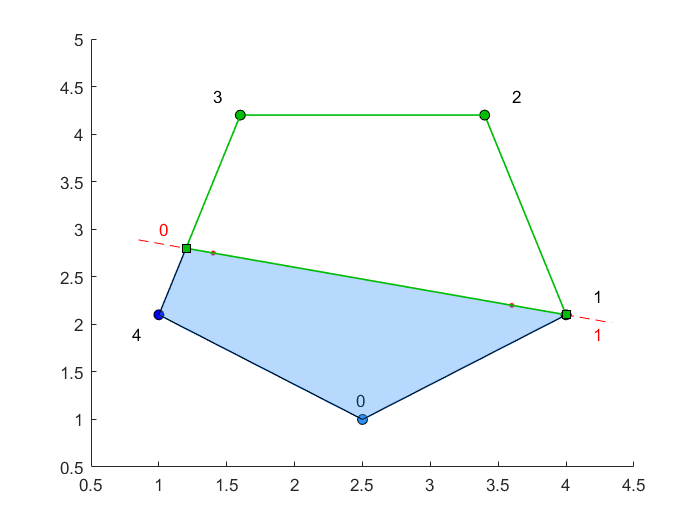


plot(points(4, 1), points(4, 2), "ko", "MarkerFaceColor", color2);
plot([points(4, 1), intersection(1, 1)], [points(4, 2), intersection(1, 2)], "Color", color2, "LineWidth", width);
plot([intersection(1, 1), intersection(2, 1)], [intersection(1, 2), intersection(2, 2)], "Color", color2, "LineWidth", width);
plot(intersection(1, 1), intersection(1, 2), "ks", "MarkerFaceColor", color2);
plot(intersection(2, 1), intersection(2, 2), "ks", "MarkerFaceColor", color2);

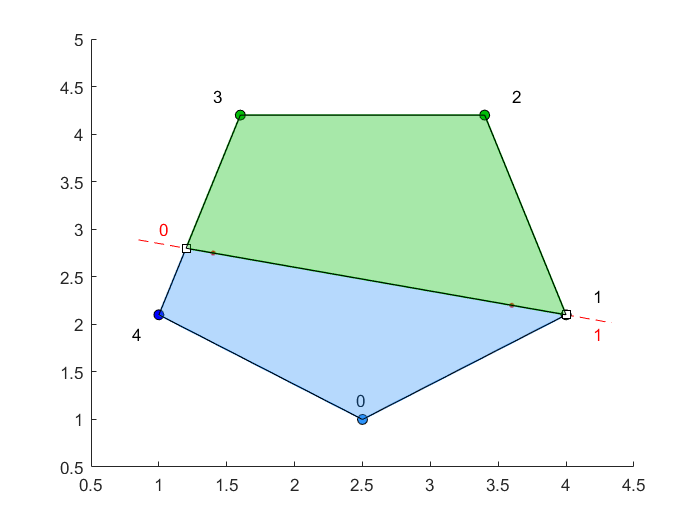

plot(intersection(1, 1), intersection(1, 2), "ks", "MarkerFaceColor", "auto");
plot(intersection(2, 1), intersection(2, 2), "ks", "MarkerFaceColor", "auto");
points2 = [
    4.0, 2.1
    3.4, 4.2
    1.6, 4.2
    1.2, 2.8
    4.0, 2.1];
polygon2 = polyshape(points2);
plot(polygon2, "FaceColor", color2);